1.4  （魔方矩阵）实时脚本

由张志涌编写、修改于 2023.1。

A = magic(3)

A =      8     1     6
     3     5     7
     4     9     2


sum(A)

ans =     15    15    15


sum(A')'

ans =     15
    15
    15


sum(diag(A))

ans =     15


sum(diag(flipud(A)))

ans =     15


sum(1:9)

ans =     45


sum(1:9)/3

ans =     15


for k = 0:3
   [rot90(A,k), rot90(A',k)]
end

ans =      8     1     6     8     3     4
     3     5     7     1     5     9
     4     9     2     6     7     2


ans =      6     7     2     4     9     2
     1     5     9     3     5     7
     8     3     4     8     1     6


ans =      2     9     4     2     7     6
     7     5     3     9     5     1
     6     1     8     4     3     8


ans =      4     3     8     6     1     8
     9     5     1     7     5     3
     2     7     6     2     9     4


det(A)

ans =   -360


X = inv(A)

X =      1.472222222222222e-01    -1.444444444444444e-01     6.388888888888887e-02
    -6.111111111111111e-02     2.222222222222222e-02     1.055555555555556e-01
    -1.944444444444445e-02     1.888888888888889e-01    -1.027777777777778e-01


format rat
X

X =       53/360        -13/90          23/360   
     -11/180          1/45          19/180   
      -7/360         17/90         -37/360   


format short
r = norm(A)

r = 15.0000

e = eig(A)

e =    15.0000
    4.8990
   -4.8990


s = svd(A)

s =    15.0000
    6.9282
    3.4641


A = sym(A)

$$A = \left(\begin{array}{ccc} 8 & 1 & 6\\ 3 & 5 & 7\\ 4 & 9 & 2 \end{array}\right)$$

sum(A), sum(A')', det(A), inv(A), e=eig(A), svd(A)

$$ans = \left(\begin{array}{ccc} 15 & 15 & 15 \end{array}\right)$$

$$ans = \left(\begin{array}{c} 15\\ 15\\ 15 \end{array}\right)$$

$$ans = -360$$

$$ans = \left(\begin{array}{ccc} \frac{53}{360} & -\frac{13}{90} & \frac{23}{360}\\ -\frac{11}{180} & \frac{1}{45} & \frac{19}{180}\\ -\frac{7}{360} & \frac{17}{90} & -\frac{37}{360} \end{array}\right)$$

$$e = \left(\begin{array}{c} 15\\ -2\,\sqrt{6}\\ 2\,\sqrt{6} \end{array}\right)$$

$$ans = \left(\begin{array}{c} 15\\ 4\,\sqrt{3}\\ 2\,\sqrt{3} \end{array}\right)$$

load durer
whos

  Name           Size                  Bytes  Class     Attributes

  A              3x3                       8  sym                 
  F            768x1024x3            2359296  uint8               
  X            648x509               2638656  double              
  X1             5x1                       8  sym                 
  X2             1x1                       8  sym                 
  X3             3x1                       8  sym                 
  ans            3x1                       8  sym                 
  caption        2x28                    112  char                
  e              3x1                       8  sym                 
  f             40x1                     320  double              
  g              1x1                       8  sym                 
  gx6            0x1                       8  sym                 
  gx7            2x1                       8  sym                 
  k              1x1                       8  double         

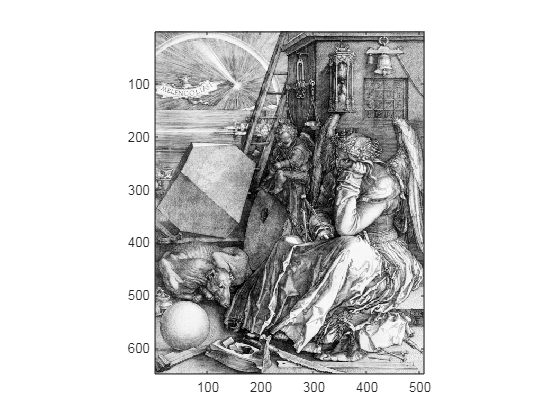

clf
image(X)
colormap(map)
axis image  

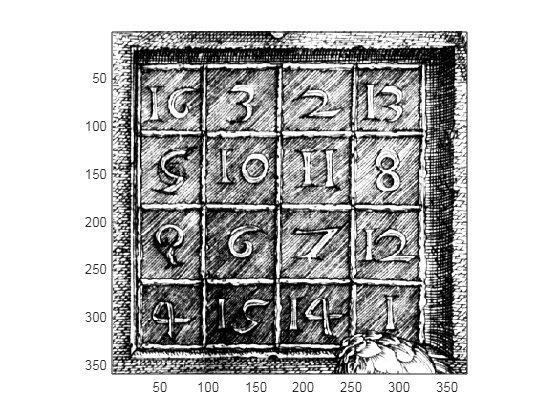

load detail
image(X)
colormap(map)
axis image

A = magic(4)

A =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


sum(A), sum(A'), sum(diag(A)), sum(diag(flipud(A)))

ans =     34    34    34    34


ans =     34    34    34    34


ans = 34

ans = 34

A = A(:, [1 3 2 4])

A =     16     3     2    13
     5    10    11     8
     9     6     7    12
     4    15    14     1


det(A)

ans = 2.4317e-13

inv(A)

ans = 1.0e+15 *

    0.5593    1.6778   -1.6778   -0.5593
   -1.6778   -5.0334    5.0334    1.6778
    1.6778    5.0334   -5.0334   -1.6778
   -0.5593   -1.6778    1.6778    0.5593


for n = 1:24, r(n) = rank(magic(n)); end
[(1:24)' r']

ans =      1     1
     2     2
     3     3
     4     3
     5     5
     6     5
     7     7
     8     3
     9     9
    10     7


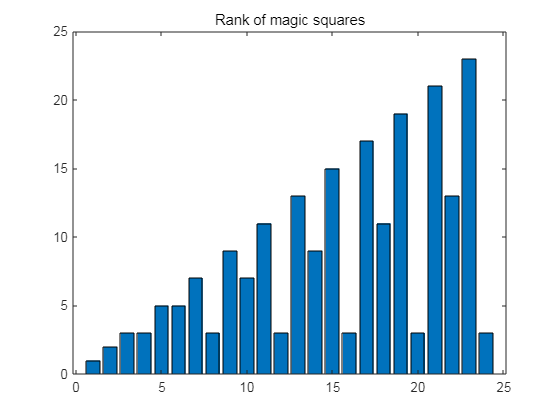

bar(r)
title('Rank of magic squares')

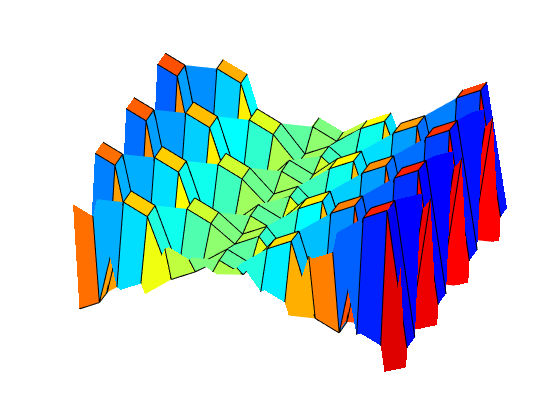


clf
n=20;       %你可以输入所喜欢的正整数
zz=magic(n);
surf(zz)
colormap(jet)
view([-72 45])
axis off

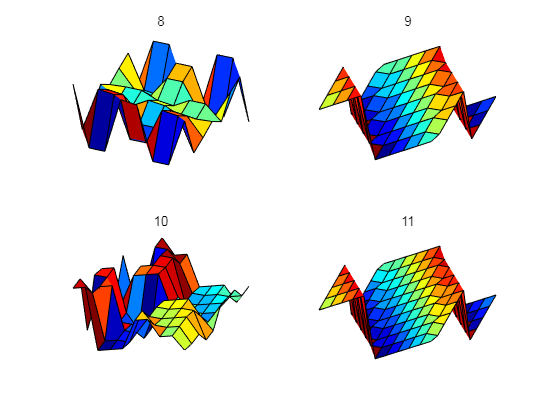

for n = 8:11
   subplot(2,2,n-7)
   surf(magic(n))
   title(num2str(n))
   axis off
   view(30,45)
   axis tight
end